clear all;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


close all;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...     0

     0

Check osense*c - A'*lam - w = 0 (stationarity):
     0
     0


 > [gurobi] Primal optimality condition in solveCobraLP satisfied.
 > [gurobi] Dual optimality condition in solveCobraLP satisfied.


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

clc;

# Localgini Thresholding Method

This code is designed to execute the global thresholding algorithm.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Set up

The Gurobi solver is initialised, as well as COBRAToolbox.

gurobi_setup;


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only b

ans = logical
   1


initCobraToolbox(false);
setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab')
changeCobraSolver('gurobi', 'all')

## Load the data

Gene expression data, the list of housekeeping genes and the metabolic model to be used are uploaded.

currentFolder = pwd
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data')
data = readtable("data_TPM.xlsx")
h_k_g = readtable('NM2ENSG.xlsx')
%model = load('Human-GEM_Cobra_v1.01.mat')
%model = model.model
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis, so it is recommended to remove these.

% [fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
% model = fluxConsistModel; % load the new model with no blocked reactions
% save('model', 'model');
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
model_genes = model.genes;
cd(currentFolder)

## Preprocessing

Depending on the dataset, different steps will be required. The points we are interested in obtaining are the ENSEMBL_IDs of the genes, the sample names, and normalising the gene expression data.

To normalise, a log10 of the data is made, to which a 1 is added to avoid that values that are 0 give -inf values.

Finally, a table is created with the new normalised data, the column names are the sample names, and the first column is the ENSEML_IDs.

%Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(7:end); 
data_to_log = table2array(data(:, 7:end));
logged_data = log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the gene expression dataset

Not all genes in the dataset are metabolism-related genes. This part of the code is responsible for obtaining the expression of the metabolic genes (metabolic_genes).

% Define new cells and new Matrixes
allGenes = {};
geneExpressionMatrix = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1} - min(log_data{:, i + 1});
    [geneList, geneExpression] = findUsedGenesLevels(model, log_data);
    allGenes = unique([allGenes; geneList]);
    tempMatrix = zeros(length(allGenes), 1);
    [~, geneIdx] = ismember(geneList, allGenes);
    tempMatrix(geneIdx) = geneExpression;
    geneExpressionMatrix = [geneExpressionMatrix, tempMatrix];
    log_data.value = [];
end

metabolic_genes = array2table(geneExpressionMatrix, 'RowNames', allGenes, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes = rmmissing(metabolic_genes, 'MinNumMissing', size(metabolic_genes, 2));

## Prepare the data

LocalGini needs a specific format in order to be used. In this section we configure the data in the structure format with the different sub-sections necessary to implement localGini 

% Separating gene names and data
genes = metabolic_genes.Properties.RowNames; % First column for gene names

% Get sample names (row names)
context = metabolic_genes.Properties.VariableNames % Assuming that 'rownames' is a function or variable containing the row names

context = 1×48 cell array
    {'BJ_Y1'}    {'BJ_Y2'}    {'BJ_Y3'}    {'BJ_OLD_1'}    {'BJ_OLD_2'}    {'BJ_OLD_3'}    {'IMR90_Y1'}    {'IMR90_Y2'}    {'IMR90_Y3'}    {'IMR90_O1'}    {'IMR90_O2'}    {'IMR90_O3'}    {'WI_38_Y1'}    {'WI_38_Y2'}    {'WI_38_Y3'}    {'WI_38_O1'}    {'WI_38_O2'}    {'WI_38_O3'}    {'HFF_PD16_1'}    {'HFF_PD16_2'}    {'HFF_PD16_3'}    {'HFF_PD74_1'}    {'HFF_PD74_2'}    {'HFF_PD74_3'}    {'MRC_5_PD32_1'}    {'MRC_5_PD32_2'}    {'MRC_5_PD32_3'}    {'MRC_5_PD72_1'}    {'MRC_5_PD72_2'}    {'MRC_5_PD72_3'}    {'HFF_PD26_1'}    {'HFF_PD26_2'}    {'HFF_PD26_3'}    {'HFF_PD46_1'}    {'HFF_PD46_2'}    {'HFF_PD46_3'}    {'HFF_PD64_1'}    {'HFF_PD64_2'}    {'HFF_PD64_3'}    {'MRC_5_PD42_1'}    {'MRC_5_PD42_2'}    {'MRC_5_PD42_3'}    {'MRC_5_PD52_1'}    {'MRC_5_PD52_2'}    {'MRC_5_PD52_3'}    {'MRC_5_PD62_1'}    {'MRC_5_PD62_2'}    {'MRC_5_PD62_3'}



% Calculate the log10 of the fitted expression data
value = metabolic_genes; % Normalize it

% Creating the structure
geneExpression = struct;
geneExpression.value = value;
geneExpression.context = context;
geneExpression.genes = genes;

## Repo pipeline

% Choice of model extraction method (has to be anyone of ['FASTCORE','iMAT','MBA','GIMME','INIT','mCADRE'])
MeM = 'FASTCORE';

% The context or samples that you are interested, in this case, all of them
contexts = context;

% Set upper and lower thresholds
ut = 75;
lt = 25;

% Specifying where threshold has to be implied (1==> implied to genes; 2==> implied to enzymes; 3==> implied to reactions)
ThS = 1; % impliying at gene level

% Reactions that are manually given higher importance
biomass_id = find(strcmp(model.rxns,'biomass_reaction'));
atp_demand_id = find(strcmp(model.rxns,'DM_atp_c_'));
coreRxn=[biomass_id atp_demand_id];

% Tolerance level above which reactions are considered as expressed
tol = 1e-4;

% Folder path to save the built models Here put your path to save the models, 
% this way (\\) is for windows, for Linux, and I think for mac it should be (/)
filename = 'C:\\Users\\PC\\OneDrive\\Documentos\\Systems_Biology_master\\Internship\\Internship\\Thresholding\\Local_gini\\';

% Building context-specific models
% [Models,RxnImp] = buildContextmodels(geneExpression,model,MeM,contexts,ut,lt,ThS,coreRxn,filename,tol);
% save('Models.mat', 'Models');
% save('RxnImp.mat', 'RxnImp');
RxI_check = load('RxnImp.mat');
RxnImp = RxI_check.RxnImp;
Model_check = load('Models.mat');
Models = Model_check.Models;

## Housekeeping genes

Now it starts the analysis for Housekeeping gene list. As it happens with the dataset, not all the housekeeping genes are related with the metabolism. We choose those ones that are related to the metabolism.

ens_hkg = h_k_g.converted_alias; 
index_names = ismember(ens_hkg, genes);
met_hkg = ens_hkg(index_names);

% Find reactions from the housekeeping genes
reactions_hkg = findRxnsFromGenes_Alicia(model, met_hkg);

Input: string of single gene or cell array of multiple genes



%Create an array with all the housekeeping reactions
fields = fieldnames(reactions_hkg); 
housekeep_react = {}; 

for i = 1:length(fields)
    field = fields{i}; 
    cellArray = reactions_hkg.(field); 

    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1}; 
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react;

% Finding unique elements and their frequency
[uniques, ~, index] = unique(housekeep_react);

## Check the housekeeping core genes

This part of the code gives the percentage of metabolic core-housekeeping genes out of the total amount of metabolic housekeeping genes 

num_models = length(Models);
results = zeros(num_models, 1); 

for i = 1:num_models
    current_model = Models{i};
    
    if isfield(current_model, 'genes')
        genes_model = current_model.genes;
        
        num_coincidences = sum(ismember(genes_model, met_hkg));
        
        percentage_coincidences = (num_coincidences / length(met_hkg)) * 100;
        
        results(i) = percentage_coincidences;
    else
        results(i) = NaN;
    end
end
HK_G_accuracy = array2table(results, 'VariableNames', {'PercentageCoincidences'});

HK_G_acc_LG = [HK_G_accuracy.PercentageCoincidences];
HK_G_acc_LG_col = HK_G_acc_LG(:);
T_Gene = table(HK_G_acc_LG_col, 'VariableNames', {'HK_G_acc_LG'});
writetable(T_Gene, "HK_G_acc_LG.xlsx", 'WriteRowNames', false);

## Check the housekeeping core reactions

This part of the code gives the percentage of metabolic core-housekeeping reactions out of the total amount of metabolic housekeeping reactions. 

num_models = length(Models);
results = zeros(num_models, 1); 
for i = 1:num_models
    current_model = Models{i};
    
    if isfield(current_model, 'rxns')
        reactions_model = current_model.rxns;
        
        num_coincidences = sum(ismember(reactions_model, uniques));
       
        percentage_coincidences = (num_coincidences / length(uniques)) * 100;
        
        results(i) = percentage_coincidences;
    else
        results(i) = NaN;
    end
end
HK_R_accuracy = array2table(results, 'VariableNames', {'PercentageCoincidencesReactions'});

HK_R_acc_LG = [HK_R_accuracy.PercentageCoincidencesReactions];
HK_R_acc_LG_col = HK_R_acc_LG(:);
T_React = table(HK_R_acc_LG_col, 'VariableNames', {'HK_R_acc_LG'});
writetable(T_React, "HK_R_acc_LG.xlsx", 'WriteRowNames', false);



## Gini coefficient for samples

% If data is a table, convert to numeric array
if istable(metabolic_genes_P)
    numericData = table2array(metabolic_genes_P);
else
    numericData = metabolic_genes_P;
end

% Preparing to store Gini coefficients
giniCoefficients = zeros(size(numericData, 1), 1);

% Apply the modified function giniUniform to each row
for i = 1:size(numericData, 1)
    giniCoefficients(i) = giniUniform(numericData(i, :), false);
end

## Plot it

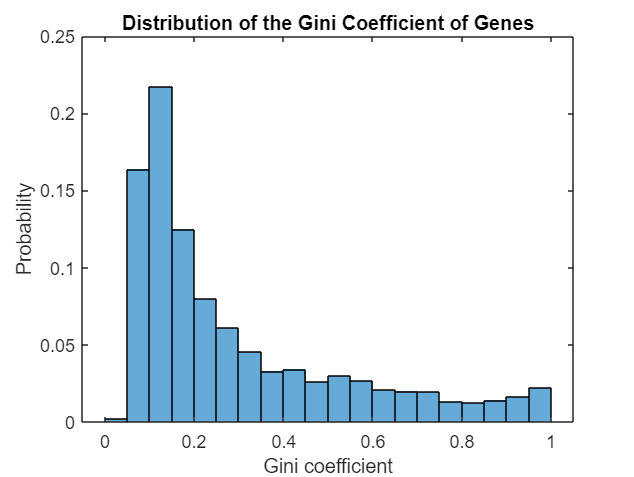

% Histogram of the Gini coefficients
figure;
histogram(giniCoefficients, 'Normalization', 'probability');
title('Distribution of the Gini Coefficient of Genes');
xlabel('Gini coefficient');
ylabel('Probability');